% a -ii
x1 = linspace(-1.5, 2.5, 200)

x1 =    -1.5000   -1.4799   -1.4598   -1.4397   -1.4196   -1.3995   -1.3794   -1.3593   -1.3392   -1.3191   -1.2990   -1.2789   -1.2588   -1.2387   -1.2186   -1.1985   -1.1784   -1.1583   -1.1382   -1.1181   -1.0980   -1.0779   -1.0578   -1.0377   -1.0176   -0.9975   -0.9774   -0.9573   -0.9372   -0.9171   -0.8970   -0.8769   -0.8568   -0.8367   -0.8166   -0.7965   -0.7764   -0.7563   -0.7362   -0.7161   -0.6960   -0.6759   -0.6558   -0.6357   -0.6156   -0.5955   -0.5754   -0.5553   -0.5352   -0.5151

x2 = ((-(1.5014+1.3155.*x1))+sqrt((1.4207.*x1.^2)+(4.3417.*x1)+2.298))/0.1422

x2 =    3.3182 + 3.9838i   3.1323 + 4.0843i   2.9463 + 4.1740i   2.7604 + 4.2537i   2.5744 + 4.3240i   2.3885 + 4.3852i   2.2025 + 4.4379i   2.0166 + 4.4822i   1.8306 + 4.5184i   1.6447 + 4.5468i   1.4587 + 4.5674i   1.2728 + 4.5803i   1.0868 + 4.5857i   0.9009 + 4.5836i   0.7149 + 4.5739i   0.5290 + 4.5566i   0.3430 + 4.5316i   0.1570 + 4.4988i  -0.0289 + 4.4580i  -0.2149 + 4.4090i  -0.4008 + 4.3514i  -0.5868 + 4.2851i  -0.7727 + 4.2095i  -0.9587 + 4.1242i  -1.1446 + 4.0285i  -1.3306 + 3.9216i  -1.5165 + 3.8027i  -1.7025 + 3.6705i  -1.8884 + 3.5236i  -2.0744 + 3.3600i  -2.2603 + 3.1771i  -2.4463 + 2.9715i  -2.6322 + 2.7379i  -2.8182 + 2.4685i  -3.0041 + 2.1497i  -3.1901 + 1.7551i  -3.3760 + 1.2125i  -3.1045 + 0.0000i  -2.3487 + 0.0000i  -1.9908 + 0.0000i  -1.7403 + 0.0000i  -1.5456 + 0.0000i  -1.3863 + 0.0000i  -1.2516 + 0.0000i  -1.1352 + 0.0000i  -1.0329 + 0.0000i  -0.9419 + 0.0000i  -0.8601 + 0.0000i  -0.7860 + 0.0000i  -0.7184 + 0.0000i  -0.6563 + 0.0000i  -0.5992 + 0.0000i  -0.54

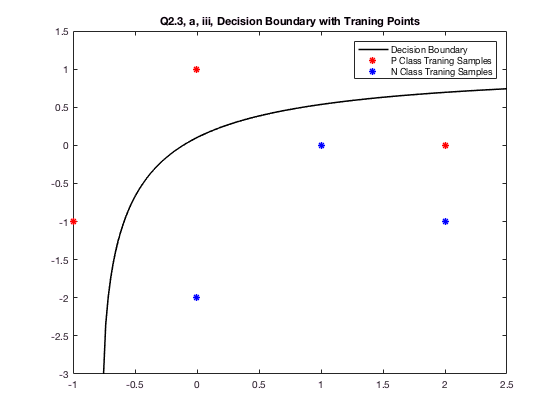

p = [];

for i = 1:length(x2)
    if isreal(x2(i))
        p = [p [x1(i); x2(i)]]; 
    end 
end

% a- iii
X_p = [-1,0,2; -1,1,0];
X_n =[0,1,2;-2,0,-1];
plot(p(1,:),p(2,:),'k-','linew',1.5)
hold on 
plot(X_p(1,:), X_p(2,:), '*r', 'linew',1.5)
plot(X_n(1,:), X_n(2,:), '*b', 'linew',1.5)
legend('Decision Boundary', 'P Class Traning Samples', 'N Class Traning Samples')
title('Q2.3, a, iii, Decision Boundary with Traning Points')
ylim([-3 1.5])
hold off 

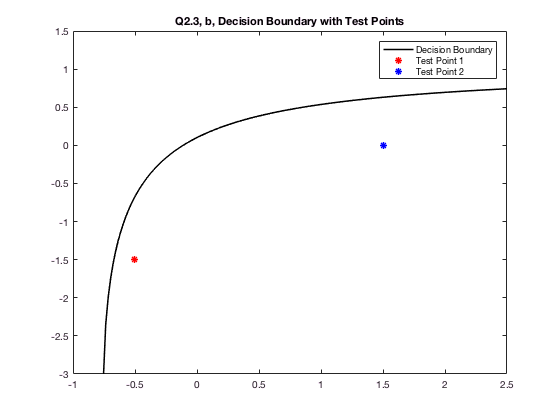


% b 
plot(p(1,:),p(2,:),'k-','linew',1.5)
hold on 
plot(-0.5, -1.5, '*r', 'linew',1.5)
plot(1.5, 0, '*b', 'linew',1.5)
legend('Decision Boundary', 'Test Point 1', 'Test Point 2')
title('Q2.3, b, Decision Boundary with Test Points')
ylim([-3 1.5])
hold off 